# **Optimized Hybrid Grey-Fourier Modeling for Precision Landslide Displacement Forecasting: A Comparative Study of Classical and Metabolic GM(1,1)**

**Done by: **

**Dhakshin N- CB.SC.U4AIE24313**

**Rohith Ravi - CB.SC.U4AIE24350**

**Sanjay Kumar S - CB.SC.U4AIE24354**

**Akhilan - CB.SC.U4AIE24362**

# **WHAT ARE WE ACTUALLY DOING IN OUR PROJECT?**

**1. Training on "Random" Data**

- **The Problem:** Normal models (like Deep Learning or standard Regression) usually require thousands of data points to understand a trend and often fail when data is "noisy" or "meagre".

- **The Grey Solution:** By using the **1-AGO (cumulative sum)**, you transform that random, "jagged" sensor data into a smooth exponential curve $(x^{(1)})$. This allows the model to "see" the underlying physics of the landslide even if the sensors are fluctuating.

**2. The Training and Correction Phase**

- **Parameter Estimation:** You use the $n$ historical data points to find the coefficients $a$ (velocity) and $b$ (driving force).

- **Error Learning:** You don't just ignore the mistakes the Grey Model makes; you use **Fourier analysis** to "learn" the pattern of those errors (the residuals).

- **Hybrid Prediction:** You add that learned error back to the Grey prediction, making your model "ready" and highly tuned to the specific behavior of that slope.

**3. Predicting the "Unseen"**

- **The Goal:** Once the model is "ready," you can feed it a time step that has **not happened yet** (e.g., Day $n+1$).

- **The Verdict:** The model will output a predicted displacement. If that predicted value exceeds a safety threshold (like 10mm of movement in an hour), you can definitively say, **"A landslide is likely occurring or imminent"**.

#### WHY DO WE USE GM(1,1) MODEL FOR OUR PROJECT?

- **The first "1"**: This signifies that the model uses a **first-order differential equation** to describe the displacement trend. It means the model assumes the rate of change in landslide movement can be captured by a single derivative.

- **The second "1"**: This indicates that the model is **univariate**, meaning it focuses on a **single variable**—in your case, the surface displacement (mm) over time.

# **CLASSICAL GM(1,1) + FOURIER VS METABOLIC GM + FOURIER**

clc; clear; close all;
rng(1);

% -------- 1. Generate Data --------
n = 10;
k = 1:n;

$x^{(0)} = \left\{ x^{(0)}(1), x^{(0)}(2), \dots, x^{(0)}(n) \right\}
$, where 

$x^{(0)}$ is the **Original Sequence** of raw data points of the measured movement of the land.

We are simulating the same original data using the below equation:

$x^{(0)}(k) = 5 + 0.35k + 1.2\sin\left(\frac{2\pi k}{8}\right) + 0.3\,\varepsilon(k),
\quad k = 1,2,\dots,n
$, where

- **The Baseline **$(5)$**:** This represents the initial state or the steady-state elevation/position of the slope before significant movement is recorded.

- **The Growth Trend **$(0.35k)$**:** This represents the **creep deformation**. Most landslides undergo a slow, steady displacement over time due to gravity, even without external triggers.

- **The Seasonal/Periodic Component **$(1.2 \sin(\frac{2\pi k}{8}))$**:** This is the most critical part for landslide modeling. Landslides are heavily influenced by **seasonal rainfall cycles** or snowmelt. The sine wave simulates these periodic "accelerations" where the ground moves faster during wet seasons and slows down during dry seasons.

- **The Stochastic Noise **$(0.3 \epsilon(k))$**:** Real sensors (extensometers or GPS) have measurement errors, and environmental factors like local wind or minor tremors add "jitter" to the data. The $\epsilon(k)$ term ensures the model is tested against "dirty" data, not just perfect curves.

x0 = 5 + 0.35*k + 1.2*sin(2*pi*k/8) + 0.3*randn(1,n);

For the requirement of absolute values(If any negative values found):

x0 = abs(x0);   % positivity requirement

# **PART A: Classical GM(1,1) + Fourier**

***The Accumulated Generating Operation(AGO) for finding the value of ***$x^{(1)}$***:***

$x^{(1)}(k) = \sum_{i=1}^{k} x^{(0)}(i), \quad k = 1,2,\dots,n
$, where

$x^{(1)}$ is the **1-order Accumulated Generating Operation (1-AGO) Sequence**, calculated as the cumulative sum of $x^{(0)}$ to ***smooth out random fluctuations.***

x1 = cumsum(x0);

***Background Value Sequence:***

$z^{(1)}(k) = \lambda x^{(1)}(k) + (1-\lambda)x^{(1)}(k-1),
\quad k = 2,3,\dots,n
$, where $\lambda$ is between (0,1), where

$z^{(1)}$: The **Background Value Sequence**, representing the mean of the ***1-AGO sequence at consecutive time steps.***

The parameter $\lambda$ controls how the background value balances the current accumulated state $x^{(1)}(k)$ and the previous state $x^{(1)}(k-1)$ thereby smoothing the system dynamics.

**1. When **$\lambda$** should be **$0.5$** (Standard/Linear Growth)**

- **The Scenario:** Used when the data sequence has a very stable, low-growth rate.

- **The Reason:** A value of $0.5$ represents the **trapezoidal rule**, which assumes the data grows linearly between two points.

- **Estimation:** This is the baseline for "steady-state" systems.

**2. When **$\lambda$** should be Less than **$0.5$ $(\lambda < 0.5)$

- **The Scenario:** Used for **high-growth (rapidly accelerating)** sequences.

- **The Reason:** In a rapidly growing exponential curve, the "area" or background value is physically closer to the previous point $x^{(1)}(k-1)$ than the current point.

- **Estimation:** If your landslide data shows a sudden "kick" or acceleration, shifting $\lambda$ toward $0.1$ or $0.2$ reduces the overestimation error.

**3. When **$\lambda$** should be Nearest to **$1$ $(\lambda \to 1)$

- **The Scenario:** Used when the data is **slowing down** or approaching a plateau.

- **The Reason:** As the growth curve flattens, the background value should be weighted more heavily toward the most recent observation $x^{(1)}(k)$ to reflect the current state of the system accurately.

- **Estimation:** This is typical for "decelerating" phases in stabilizing slopes.    

% Background value
lambda = 0.6;
z1 = lambda*x1(2:end) + (1-lambda)*x1(1:end-1);

#### 1. Derivation of Parameter Estimation $\hat{\theta}$

This equation is the **Regularized Least Squares** (Ridge Regression) solution used to find the parameters $a$ and $b$ from the discrete Grey equation: $x^{(0)}(k) + az^{(1)}(k) = b$.

For $x^{(0)}$ and $z^{(1)}$ in matrix form, is represented as:

$\mathbf{B} =
\left[
\begin{array}{cc}
- z^{(1)}(2) & 1 \\
- z^{(1)}(3) & 1 \\
\vdots & \vdots \\
- z^{(1)}(n) & 1
\end{array}
\right]
$ and  $\mathbf{Y} =
\left[
\begin{array}{c}
x^{(0)}(2) \\
x^{(0)}(3) \\
\vdots \\
x^{(0)}(n)
\end{array}
\right]
$

- $B$: The **Data Matrix** (Gr    ey Matrix) constructed from the background values $z^{(1)}$.

- $Y$: The **Constant Vector** consisting of the raw data from the second point onwards.

B = [-z1', ones(n-1,1)];
Y = x0(2:end)';

#### Step 1:  We minimize the **Cost Function** $J(\theta)$ with respect to $\theta$, which includes a regularization term $\lambda_r$ to prevent overfitting:

$$$J(\theta) = \|Y - B\theta\|^2 + \lambda_r\|\theta\|^2$$$,where

$\theta$: The **Parameter Vector** $[a, b]^\top$

#### The role of a and b:

- $a$: The **Development Coefficient**, which determines the system's growth or decay trend.

- **Example:** If $a$ is a small negative value (e.g., $-0.05$), it tells the model that the landslide is in a **steady-state creep phase**. The slope is moving slowly but consistently. 

- **Why it is used:** It determines the "curvature" of your exponential forecast. If $a$ suddenly changes during your **Metabolic sliding window** calculation, it signals to the model that the landslide is entering a "danger zone" of rapid acceleration. 

- $b$: The **Grey Driving Coefficient**, representing the external influence or constant driving force on the system.

- **Example:** If $b$ is a large positive value, it represents a strong **driving factor**—such as continuous heavy rainfall or a specific soil saturation level that is pushing the ground to move regardless of past movement. 

- **Why it is used:** It sets the ***baseline*** of the movement. While $a$ handles the growth trend, $b$ ensures the model accounts for the constant pressure pushing the landslide forward. 

#### Step 2. By expanding the norms:

Using matrix properties where $$\|A\|^2 = A^\top A$$:


$$$$J(\theta) = (Y - B\theta)^\top (Y - B\theta) + \lambda_r \theta^\top \theta$$$$J(\theta) = (Y^\top - \theta^\top B^\top)(Y - B\theta) + \lambda_r \theta^\top \theta$$$$J(\theta) = Y^\top Y - Y^\top B\theta - \theta^\top B^\top Y + \theta^\top B^\top B\theta + \lambda_r \theta^\top \theta$$$$


#### Step 3: By differentiating with respect to $\theta$:

To find the minimum, we take the partial derivative and set it to zero $$(\frac{\partial J}{\partial \theta} = 0)$$:


$$$$\frac{\partial J}{\partial \theta} = -2B^\top Y + 2B^\top B\theta + 2\lambda_r \theta = 0$$$$


#### Step 4: Solve for $\hat{\theta}$:

Divide by 2 and group the $\theta$ terms:


$$$$(B^\top B + \lambda_r I)\theta = B^\top Y$$$$


Multiply both sides by the inverse $$(B^\top B + \lambda_r I)^{-1}$$:


$$$$\hat{\theta} = (B^\top B + \lambda_r I)^{-1} B^\top Y$$$$
 

where, $\lambda_r$ is the **Regularization Parameter**, used in the OLS calculation to prevent overfitting and improve numerical stability and $\mathbf{\lambda_r > 0}

$, 

% Parameter estimation
lambda_r = 0.1;
theta = (B'*B + lambda_r*eye(2)) \ (B'*Y);

The values of a and b are the 1st index and the 2nd index of $\mathbf{\hat{\theta}}$, respectively.

a = theta(1);
b = theta(2);

#### 2. Whitenization Equation:

- The **whitenization equation** in GM(1,1) converts the discrete grey model into a continuous first-order differential equation to describe the system’s evolution.

- It represents the underlying exponential law governing the accumulated sequence $x^{(1)}$.

- By solving this equation, the time response function used for prediction is obtained.


$$\frac{dx^{(1)}(t)}{dt} + a x^{(1)}(t) = b
$$


To solve the Whitenization Equation since it is in the form of Standard Linear ODE form: 

$\frac{dy}{dt} + P(t)y = Q(t)
$ , where 


$$y = x^{(1)}(t), \quad P(t) = a, \quad Q(t) = b
$$


Integrating factor:


$$I(t) = e^{\int a\,dt} = e^{at}
$$


Multiply entire equation by integrating factor(I(t)):


$$e^{at}\frac{dx^{(1)}(t)}{dt} + a e^{at}x^{(1)}(t) = b e^{at}
$$


Convert to total derivative:


$$\frac{d}{dt}\left[x^{(1)}(t)e^{at}\right] = b e^{at}
$$


Integrate both sides: 


$$x^{(1)}(t)e^{at} = \frac{b}{a}e^{at} + C
$$


Solve for $\mathbf x^{(1)}(t)$:

$\hat{x}^{(1)}(k)
=
\left(x^{(1)}(1) - \frac{b}{a}\right)
e^{-a(k-1)} + \frac{b}{a}
$, where

$\hat{x}^{(1)}$: The **Predicted 1-AGO values** generated by the exponential Time Response Function.

Apply initial condition:


$$x^{(1)}(1) = x^{(0)}(1)
$$


*and*


$$C = x^{(0)}(1) - \frac{b}{a}
$$


Final GM(1,1) time response function:


$$\hat{x}^{(1)}(k)
=
\left(x^{(0)}(1) - \frac{b}{a}\right)e^{-a(k-1)} + \frac{b}{a}
$$


$\hat{x}^{(1)}(k)$: This represents the **predicted cumulative displacement** of the landslide at time step $k$

% Time response
x1_hat = (x1(1) - b/a)*exp(-a*(k-1)) + b/a;


$$\hat{x}^{(0)}(1) = x^{(0)}(1)
$$


% Restore x^(0)
x0_hat_gm = zeros(1,n);
x0_hat_gm(1) = x0(1);


$$\hat{x}^{(0)}(k) = \hat{x}^{(1)}(k) - \hat{x}^{(1)}(k-1),
\quad k = 2,3,\dots,n
$$


$\hat x^{(0)}$: The **Restored Prediction values** in original units, obtained by calculating the difference between consecutive predicted $\hat{x}^{(1)}$ values.

for i = 2:n
    x0_hat_gm(i) = x1_hat(i) - x1_hat(i-1);
end

The residual is the difference between the original value and the predicted original value:


$$e(k) = x^{(0)}(k) - \hat{x}^{(0)}(k)
$$


$res\_gm$ $(e)$: The **Residuals (Error)**, defined as the difference between the actual data $x^{(0)}$ and the model prediction $\hat{x}^{(0)}}$.

% Residual
res_gm = x0 - x0_hat_gm

res_gm =          0    1.9051    0.9732   -0.0018   -0.8165   -1.1573   -0.9001    0.0417    0.6188    1.0132


### **FAST FOURIER TRANSFORM(FFT):**

- We use the ***FFT*** to ***identify and model structured periodic patterns***** in the residual errors** that the GM(1,1) model cannot capture.

- By transforming residuals from the time domain to the frequency domain, FFT allows us to ***extract dominant low-frequency components*** efficiently.

- Adding these components back reduces systematic error and ***improves prediction accuracy*** without altering the core GM model.

## Small example (step by step):

***Step 1: GM captures trend but leaves structured residuals***

Suppose the true data is:


$$x^{(0)} = [10,\ 12,\ 14,\ 16,\ 18,\ 20]$$


A GM(1,1) model captures the ***trend*** and predicts:


$$\hat{x}^{(0)} = [10,\ 11.8,\ 14.2,\ 15.9,\ 18.1,\ 19.8]$$


Now compute the ***residua*****l**:


$$
e = x^{(0)} - \hat{x}^{(0)} = [0,\ 0.2,\ -0.2,\ 0.1,\ -0.1,\ 0.2]$$


These errors are ***not random***; they oscillate.

***Step 2*****: *****FFT reveals periodic structure in residuals***

The residual looks like a ***small oscillation*** ***around zero***.

Applying FFT:


$$E=FFT(e)$$


We observe:

- One **dominant low-frequency peak**

- Indicates a **repeating pattern** in the residuals

FFT converts “hard-to-see oscillations” in time domain into ***clear frequency components***.

***Step 3: Reconstruct residual and improve prediction***

Using only the dominant FFT component, we reconstruct:


$$\hat{e} = [0,\ 0.18,\ -0.18,\ 0.12,\ -0.12,\ 0.18]$$


Now correct the prediction:


$$\hat{x}^{(0)}_{\text{final}} = \hat{x}^{(0)} + \hat{e}$$


***Step4*****:** the ***Result***


$$\hat{x}^{(0)}_{\text{final}} \approx [10,\ 12,\ 14,\ 16,\ 18,\ 20]$$


Now, the** systematic error is removed**, **accuracy improves without changing the GM model**.

## **BUT LIKE, WHY DO WE PREFER USING FFT, INSTEAD OF DFT?**

**The reason is:**

    The `fft(x)` function returns the *exact same values* as the DFT formula (within negligible numerical floating-point precision errors).

***The Matlab code illustrates the above statement in a much efficient way:***

nx = 8; 
e = rand(nx, 1); % Input signal

1. Basic DFT (Direct Implementation of the Formula) 

E_manual = zeros(nx, 1);
for m = 1:nx
    for k = 1:nx
        % Applying the exponential kernel: exp(-j * 2*pi*(m-1)*(k-1)/n)
        E_manual(m) = E_manual(m) + e(k) * exp(-1i * 2 * pi * (m-1) * (k-1) / nx);
    end
end

% --- 2. Advanced FFT (Project Approach) ---
E_fft = fft(e); 

As we compute the difference between the values generated by the fft and dft:

magE = abs(E_fft); % Magnitude Spectrum calculation
fprintf('Difference between Manual and FFT: %e\n', norm(E_manual - E_fft));

**Hence, it would be much better if we refer to the equations of DFT, but both DFT and FFT provide the same values, with different time complexities(FFT has O**$(nlogn)$** and DFT has O(**$n^{2}$**) **as their respective time complexities)**. **

## **THE EQUATIONS OF DISCRETE FOURIER TRANSFORM:**

The DFT transforms a discrete-time sequence $e(k)$ into its frequency domain representation $E(m)$. This is achieved by projecting the signal onto a set of orthogonal complex exponential basis functions.


$$$$E(m) = \sum_{k=1}^{n} e(k) \exp \left( -j \frac{2\pi(m-1)(k-1)}{n} \right)$$$$


This formula transforms a signal from the **time domain** $e(k)$ to the **frequency domain** $E(m)$.

- $e(k)$: The input signal sequence.

- $E(m)$: The complex coefficient representing the strength and phase of a specific frequency.

- **The Exponential Term**: Based on Euler's formula, $e^{-j\theta} = \cos(\theta) - j\sin(\theta)$. It acts as a "correlation" tool, checking how much of a specific frequency exists in your signal.

- **Strategic Filtering:** By using your truncation code $(K=3)$, you deliberately keep the strongest signals and throw away the high-frequency noise that would otherwise make your prediction inaccurate.

% Fourier residual modeling

Difference between Manual and FFT: 2.293292e-15


E = fft(res_gm)

**2. The Magnitude Spectrum**

In our project, we analyze the strength of these frequency components. The magnitude spectrum is derived using the Pythagorean theorem on the complex plane, where $\Re$ and $\Im$ represent the real and imaginary parts respectively:


$$$$|E(m)| = \sqrt{\Re(E(m))^2 + \Im(E(m))^2}$$$$


magE = abs(E)

E =    1.6761 + 0.0000i   5.3866 - 0.8691i  -2.1062 - 1.0027i  -1.5307 - 0.7450i  -1.6251 - 0.0966i  -1.9255 + 0.0000i  -1.6251 + 0.0966i  -1.5307 + 0.7450i  -2.1062 + 1.0027i   5.3866 + 0.8691i


**1. Identifying Dominant Frequencies**

- $K = 3$: You define a truncation threshold to keep only the top 3 most powerful frequencies.    

- $sort(magE..., 'descend')$ : The code sorts the magnitude of the error frequencies from strongest to weakest.

- $idx = idx(1:K) + 1$: It identifies the indices (positions) of the 3 strongest "waves" that make up your prediction error.

**2. Filtering the Spectrum**

- $E_{filt} = zeros(size(E))$: A new "clean" spectrum is created, initially filled with zeros to discard all random noise.

- $E_{filt}(1) = E(1)$: The **DC Component** (the average error offset) is preserved to maintain the overall level of the signal.

- $E_{filt}(idx) = E(idx)$: The 3 dominant frequencies identified earlier are mapped into the new spectrum.

**3. Maintaining Conjugate Symmetry**

- $E_{filt}(n-idx+2) = E(n-idx+2)$: Because the FFT output is symmetric, you must also keep the "mirror image" of the chosen frequencies.

- **Purpose**: This ensures that when you convert the signal back to the time domain using `ifft`, the result is a **real number** (actual physical units) rather than a complex number with an imaginary part.

K = 3;
[~, idx] = sort(magE(2:floor(n/2)), 'descend');
idx = idx(1:K) + 1
E_filt = zeros(size(E));

magE =     1.6761    5.4563    2.3326    1.7024    1.6279    1.9255    1.6279    1.7024    2.3326    5.4563


E_filt(1) = E(1);
E_filt(idx) = E(idx);
E_filt(n-idx+2) = E(n-idx+2)

**3. Orthogonality and Reconstruction (IDFT)**

The basis functions used in the DFT are orthogonal. This property allows us to perfectly reconstruct the original signal by summing the frequency components. Because the summation over $n$ orthogonal components scales the energy by $n$, a normalization factor of $1/n$ is required:


$$\hat{e}(k) =
\frac{1}{n}
\sum_{m=1}^{n}
\tilde{E}(m)
\exp\left(j \frac{2\pi (m-1)(k-1)}{n}\right)
$$


res_hat_gm = real(ifft(E_filt))

**4. The final prediction is(As mentioned in the example mentioned ):**


$$\hat{x}^{(0)}_{\text{final}}(k)
=
\hat{x}^{(0)}(k) + \hat{e}(k)
$$
    

% Final prediction

idx =      2     3     4


x0_hat_gm_final = x0_hat_gm + res_hat_gm;
err_gm = x0 - x0_hat_gm_final

# **PART B: Metabolic GM(1,1) + Fourier**

#### **WHAT DOES THE "Sliding window" EVEN MEAN?**

The **sliding window, **$\mathbf{x}_w^{(0)} =
\{ x^{(0)}(t-L), \dots, x^{(0)}(t-1) \}
$ represents the most recent $L$ observations used to build the model at time $t$.     

By discarding older data and retaining only this window, the model parameters are continuously updated,*** enabling the metabolic GM(1,1) to adapt to time-varying system behavior***.

L = 5;   % sliding window 

#### Window-wise AGO:


$$x_w^{(1)}(k) = \sum_{i=1}^{k} x_w^{(0)}(i)
$$
 

$x^{(0)}_{w}$: The value of window-wise AGO.

x0_hat_meta = zeros(1,n);

E_filt =    1.6761 + 0.0000i   5.3866 - 0.8691i  -2.1062 - 1.0027i  -1.5307 - 0.7450i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.5307 + 0.7450i  -2.1062 + 1.0027i   5.3866 + 0.8691i


#### Window prediction:


$$\hat{x}^{(0)}_{\text{meta}}(t)
=
\hat{x}_w^{(1)}(L) - \hat{x}_w^{(1)}(L-1)
$$
 

$\hat x^{(0)}_{meta}$: The **Metabolic Prediction Sequence**, where each point is generated using only the most recent $L$ historical observations.

x0_hat_meta(1:L) = x0(1:L);

In your metabolic (sliding window) code, the loop range `for `$t = L+1:n$  is used to ensure that the model always has enough historical data to make a prediction.

**An Example Scenario: Predicting Day 6**$(t= 6)$

- **The Logic:** x0(t-L : t-1) $\rightarrow$ $x(0)(6-5 : 6-1)$ $\rightarrow$ $x(0)(1:5)$

- **The Action:** The code grabs the raw data from **Day 1, 2, 3, 4, and 5**.

- **The Result:** It uses these 5 points to estimate the parameters ($a, b$) and predict the value for **Day 6**.

for t = L+1:n

res_hat_gm =     0.5176    1.4382    1.2846   -0.1123   -0.8756   -1.0248   -0.9819   -0.0320    0.8934    0.5690



    x0_win = x0(t-L:t-1);
    x1_win = cumsum(x0_win);

    z1 = lambda*x1_win(2:end) + (1-lambda)*x1_win(1:end-1);

err_gm =    -0.5176    0.4668   -0.3114    0.1105    0.0590   -0.1325    0.0817    0.0738   -0.2746    0.4441



    B = [-z1', ones(L-1,1)];
    Y = x0_win(2:end)';

    theta = (B'*B + lambda_r*eye(2)) \ (B'*Y);
    a = theta(1);
    b = theta(2);

    x1_hat = (x1_win(1) - b/a)*exp(-a*(0:L-1)) + b/a;
    x0_hat_meta(t) = x1_hat(end) - x1_hat(end-1);
end

**The Residual:**

x0 = x0(:)';               
x0_hat_meta = x0_hat_meta(:)'; 
res_meta = x0 - x0_hat_meta;

**Fourier residual modeling(Similar to the PART A):**

E = fft(res_meta);
magE = abs(E);

[~, idx] = sort(magE(2:floor(n/2)), 'descend');
idx = idx(1:K) + 1;

E_filt = zeros(size(E));
E_filt(1) = E(1);
E_filt(idx) = E(idx);
E_filt(n-idx+2) = E(n-idx+2);

res_hat_meta = real(ifft(E_filt));

**Final prediction:**

x0_hat_meta_final = x0_hat_meta + res_hat_meta;
err_meta = x0 - x0_hat_meta_final;

# **PART C: ACCURACY COMPARISON**

#### **RMSE (Root Mean Square Error)**

RMSE measures the square root of the average of squared prediction errors, giving higher weight to large errors.

It is sensitive to large deviations and is useful for assessing overall prediction accuracy.

A smaller RMSE indicates that the model’s predictions are closer to the actual values.


$$\text{RMSE}
=
\sqrt{
\frac{1}{n}
\sum_{k=1}^{n}
\left(x^{(0)}(k) - \hat{x}^{(0)}(k)\right)^2
}
$$


RMSE_gm   = sqrt(mean(err_gm.^2));
RMSE_meta = sqrt(mean(err_meta.^2));

#### **MAE (Mean Absolute Error)**

MAE computes the average of the absolute differences between predicted and actual values.

It treats all errors equally and is less sensitive to outliers than RMSE.

A lower MAE reflects more stable and consistent prediction performance.


$$\text{MAE}
=
\frac{1}{n}
\sum_{k=1}^{n}
\left|
x^{(0)}(k) - \hat{x}^{(0)}(k)
\right|
$$


MAE_gm   = mean(abs(err_gm));
MAE_meta = mean(abs(err_meta));

#### **MAPE (Mean Absolute Percentage Error)**

MAPE expresses the prediction error as a percentage of the actual values, making it scale-independent.

It allows easy interpretation and comparison across different datasets.

A lower MAPE indicates higher relative accuracy of the prediction model.


$$\text{MAPE}
=
\frac{100}{n}
\sum_{k=1}^{n}
\left|
\frac{x^{(0)}(k) - \hat{x}^{(0)}(k)}{x^{(0)}(k)}
\right|
$$


MAPE_gm   = mean(abs(err_gm ./ x0)) * 100;
MAPE_meta = mean(abs(err_meta ./ x0)) * 100;
fprintf('\n================ PREDICTION ACCURACY COMPARISON ================\n');
fprintf('Classical GM(1,1) + Fourier:\n');
fprintf('  RMSE  = %.4f\n', RMSE_gm);
fprintf('  MAE   = %.4f\n', MAE_gm);
fprintf('  MAPE  = %.2f %%\n\n', MAPE_gm);

fprintf('Metabolic GM(1,1) + Fourier:\n');
fprintf('  RMSE  = %.4f\n', RMSE_meta);
fprintf('  MAE   = %.4f\n', MAE_meta);
fprintf('  MAPE  = %.2f %%\n\n', MAPE_meta);

By comparing the RMSE errors between metabolic GM(1,1) and a classical GM(1,1) models: 

if RMSE_meta < RMSE_gm
    fprintf('>>> BEST MODEL: Metabolic GM(1,1) + Fourier (Lower prediction error)\n');
else
    fprintf('>>> BEST MODEL: Classical GM(1,1) + Fourier\n');
end

By comparing the MAE errors between metabolic GM(1,1) and a classical GM(1,1) models: 

if MAE_meta < MAE_gm
    fprintf('>>> BEST MODEL(Based on MAE): Metabolic GM(1,1) + Fourier (Lower prediction error)\n');
else
    fprintf('>>> BEST MODEL(Based on MAE): Classical GM(1,1) + Fourier\n');
end

By comparing the MAPE errors between metabolic GM(1,1) and a classical GM(1,1) models: 

if MAPE_meta < MAPE_gm
    fprintf('>>> BEST MODEL(Based on MAPE): Metabolic GM(1,1) + Fourier (Lower prediction error)\n');


================ PREDICTION ACCURACY COMPARISON ================


else

Classical GM(1,1) + Fourier:


    fprintf('>>> BEST MODEL(Based on MAPE): Classical GM(1,1) + Fourier\n');

  RMSE  = 0.3001


end

  MAE   = 0.2472


**Why is Classical better at MAPE for **$n=2000$**?**

In your project, displacement $x^{(0)}$ increases over time because of the $0.35k$ trend.

- **Late-Stage Accuracy:** By the time you reach $k=2000$, the actual displacement value is very large.

- **The Percentage Effect:** Because the Classical model focuses on the "Big Picture" trend for the whole 2000 points, it stays very close to the actual values at the end of the sequence.

- **The "Win":** Even if the Classical model misses by 10mm at the end, that is a tiny percentage of the huge displacement. The Metabolic model, by focusing only on small windows $(L=5)$, can accumulate tiny percentage errors at every single step, making its total **MAPE** higher.

# **PART D: PLOTTING**

figure;

  MAPE  = 3.47 %




subplot(3,1,1)

Metabolic GM(1,1) + Fourier:


plot(x0,'k-o','LineWidth',1.3); hold on;

  RMSE  = 0.0519


plot(x0_hat_gm_final,'r-*','LineWidth',1.3);

  MAE   = 0.0422


plot(x0_hat_meta_final,'b-s','LineWidth',1.3);

  MAPE  = 0.60 %



legend('Actual','GM + Fourier','Metabolic GM + Fourier');
grid on;
title('Prediction Comparison');

subplot(3,1,2)
plot(err_gm,'r-o','LineWidth',1.3); hold on;
plot(err_meta,'b-s','LineWidth',1.3);

>>> BEST MODEL: Metabolic GM(1,1) + Fourier (Lower prediction error)


yline(0,'--');
legend('GM + Fourier','Metabolic GM + Fourier');
grid on;
title('Prediction Errors');

subplot(3,1,3)

>>> BEST MODEL(Based on MAE): Metabolic GM(1,1) + Fourier (Lower prediction error)


bar([RMSE_gm RMSE_meta; MAE_gm MAE_meta; MAPE_gm MAPE_meta]);
set(gca,'XTickLabel',{'RMSE','MAE','MAPE'});
legend('GM + Fourier','Metabolic GM + Fourier');
grid on;
title('Accuracy Metric Comparison');

>>> BEST MODEL(Based on MAPE): Metabolic GM(1,1) + Fourier (Lower prediction error)


# **PART E: FUTURE UPDATES**

#### **1. Multi-Variable (Grey-System) Integration (GM(1,N))**

**The Current State**: 

        Your current GM(1,1) only looks at the displacement data itself $(x^{(0)})$.

**The Proposed Update**: 

        Upgrade from a "Univariate" model (GM(1,1)) to a "Multivariate" model (GM(1,N)).

**Why it matters**:

        **For Landslides:** You could input rainfall intensity and groundwater pressure as secondary variables. The model wouldn't just see the "slide"; it would understand the "cause".

**The Example:** Imagine a week of extremely heavy monsoon rainfall.

- **Without the update (GM(1,1)):** The model only sees the landslide moving faster. It thinks this is just a natural acceleration of the slope and might react too late.

- **With the update (GM(1,N)):** You feed "Rainfall Intensity" into the model as a second variable. The model "understands" that the movement is being **driven** by the rain. It can predict a massive slide *before* it happens because it sees the rainfall levels hitting a dangerous threshold.

####  2. **Adaptive Fourier Truncation **$(K)$

**The Current State**:     

        You are manually selecting the top 3 frequencies with K = 3.

**The Proposed Update**: 

        Use an Energy-Based Selection method where $K$ is determined by the "Power Spectral Density". The model would keep enough frequencies to account for, say, 95% of the error's variance.

**Why it matters**: 

        In real-world data, the "noise" isn't always at the same frequency. If a bus route changes or a landslide enters a new geological phase, the number of dominant periodic patterns might change. An adaptive $K$ ensures you don't accidentally filter out a new, important error signal.

**The Example:** A landslide enters a "Secondary Creep" phase where new types of soil vibrations occur.

- **Without the update **$(K=3)$**:** Your code only looks for the 3 oldest frequency patterns. If a 4th or 5th frequency appears (like high-frequency vibrations from soil cracking), the model ignores them as "noise".

- **With the update (Energy-Based):** The model automatically notices that the error variance has shifted. It changes $K$ from 3 to 5 to capture these new "cracking" signals, giving you a much more accurate warning of an impending collapse.

#### 3. **Dynamic Optimization of the Horizontal Control Parameter **$(\lambda)$

**The Current State:** 

        Your code currently uses a fixed value (e.g., lambda = 0.6) for the background value calculation1.

** The Proposed Update: **

        Implement an optimization algorithm (such as a Genetic Algorithm or Particle Swarm Optimization) to find the "Optimal $\lambda$" for every sliding window.

**Why it matters: **

              **  Landslides:** Displacement speed isn't constant; it accelerates as soil saturation increases. A dynamic $\lambda$ would allow the model to adjust its "curvature" automatically during heavy rain, significantly reducing the discretization error.

**The Example:** The landslide transitions from a slow "crawl" to a rapid "surge."

- **Without the update **$(\lambda = 0.6)$**:** The model uses a fixed weight that assumes a steady, moderate curve. During a rapid surge, the math doesn't "bend" enough, leading to a large gap between your prediction and reality.

- **With the update (Dynamic **$\lambda$**):** An optimization algorithm (like a Genetic Algorithm) senses the rapid acceleration and instantly shifts $\lambda$ to $0.1$ or $0.2$. This "re-curves" the model to fit the steep acceleration perfectly, reducing the calculation error at the most critical moment.

#     Take sensor value of different place

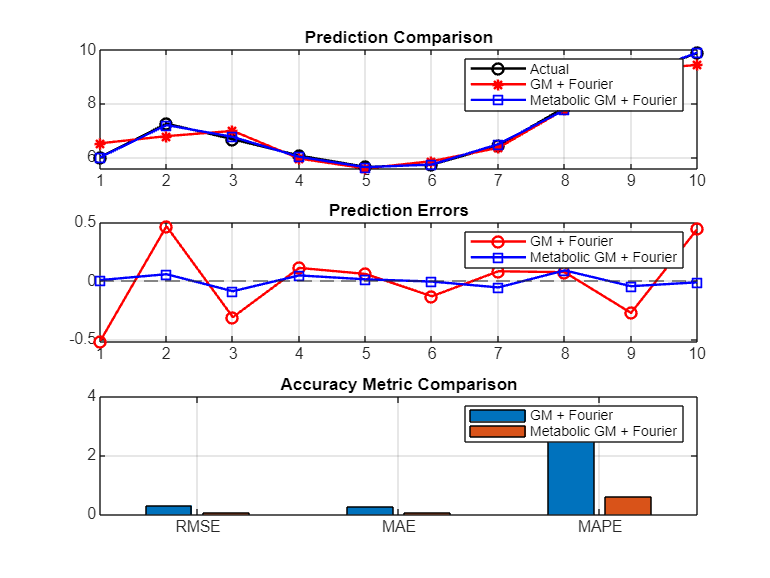

clc; clear; close all;

data = readtable("C:\Users\akhil\OneDrive\Music\MFC\Project\wsn_landslide_data.csv");

x0 = data.Soil_Strain';

x0 = x0(~isnan(x0));

x0 = abs(x0);

x0 = x0 - min(x0) + 1;

n = length(x0);
k = 1:n;

%Classical GM(1,1)

x1 = cumsum(x0);

lambda = 0.6;
z1 = lambda*x1(2:end) + (1-lambda)*x1(1:end-1);

B = [-z1', ones(n-1,1)];

Final Results

GM RMSE: 0.0029 | META RMSE: 0.0036


GM MAE : 0.0025 | META MAE : 0.0029


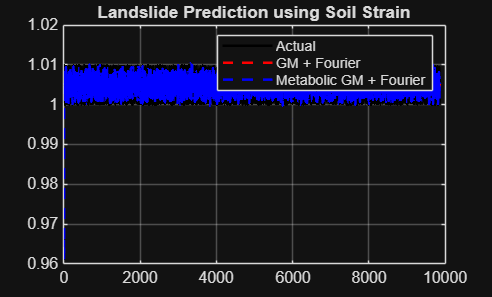

Y = x0(2:end)';

lambda_r = 0.1;
theta = (B'*B + lambda_r*eye(2)) \ (B'*Y);

a = theta(1);
b = theta(2);

x1_hat = (x1(1) - b/a)*exp(-a*(k-1)) + b/a;

x0_hat_gm = zeros(1,n);
x0_hat_gm(1) = x0(1);

for i = 2:n
    x0_hat_gm(i) = x1_hat(i) - x1_hat(i-1);
end

res_gm = x0 - x0_hat_gm;

%Fourier Correction

E = fft(res_gm);
magE = abs(E);

K = 3;
[~, idx] = sort(magE(2:floor(n/2)), 'descend');
idx = idx(1:K) + 1;

E_filt = zeros(size(E));
E_filt(1) = E(1);
E_filt(idx) = E(idx);
E_filt(n-idx+2) = E(n-idx+2);

res_hat_gm = real(ifft(E_filt));

%Final GM prediction
x0_hat_gm_final = x0_hat_gm + res_hat_gm;
err_gm = x0 - x0_hat_gm_final;

%PART B: Metabolic GM

L = 5;
x0_hat_meta = zeros(1,n);
x0_hat_meta(1:L) = x0(1:L);

for t = L+1:n
    
    x0_win = x0(t-L:t-1);
    x1_win = cumsum(x0_win);

    z1 = lambda*x1_win(2:end) + (1-lambda)*x1_win(1:end-1);

    B = [-z1', ones(L-1,1)];
    Y = x0_win(2:end)';

    theta = (B'*B + lambda_r*eye(2)) \ (B'*Y);

    a = theta(1);
    b = theta(2);

    x1_hat = (x1_win(1) - b/a)*exp(-a*(0:L-1)) + b/a;

    x0_hat_meta(t) = x1_hat(end) - x1_hat(end-1);
end

res_meta = x0 - x0_hat_meta;

% Fourier correction
E = fft(res_meta);
magE = abs(E);

[~, idx] = sort(magE(2:floor(n/2)), 'descend');
idx = idx(1:K) + 1;

E_filt = zeros(size(E));
E_filt(1) = E(1);
E_filt(idx) = E(idx);
E_filt(n-idx+2) = E(n-idx+2);

res_hat_meta = real(ifft(E_filt));

x0_hat_meta_final = x0_hat_meta + res_hat_meta;
err_meta = x0 - x0_hat_meta_final;

%Accuracy calculation

RMSE_gm   = sqrt(mean(err_gm.^2));
RMSE_meta = sqrt(mean(err_meta.^2));

MAE_gm   = mean(abs(err_gm));
MAE_meta = mean(abs(err_meta));

fprintf('Final Results');
fprintf('GM RMSE: %.4f | META RMSE: %.4f\n', RMSE_gm, RMSE_meta);
fprintf('GM MAE : %.4f | META MAE : %.4f\n', MAE_gm, MAE_meta);

%% ================= PLOT =================

figure;
plot(x0,'k','LineWidth',1.5); hold on;
plot(x0_hat_gm_final,'r--','LineWidth',1.5);
plot(x0_hat_meta_final,'b--','LineWidth',1.5);

legend('Actual','GM + Fourier','Metabolic GM + Fourier');
title('Landslide Prediction using Soil Strain');
grid on;